clc; clear; close all;


% [in, Fs] = audioread('Wagner.wav');  % Assuming input audio is sampled at 11,025 Hz
% if Fs == 11025
%     out = srconvert(in);  % Convert to 24,000 Hz
%     audiowrite('output_audio.wav', out, 24000);  % Write the output audio
%     disp('Output audio file saved as output_audio.wav');
%     % sound(out, 24000); % Play the sound
% else
%     error('Input sampling rate must be 11,025 Hz');
% end

Stage 1 filter length: 319 taps
Stage 1 cutoff frequency: 0.142857 (normalized by Nyquist)


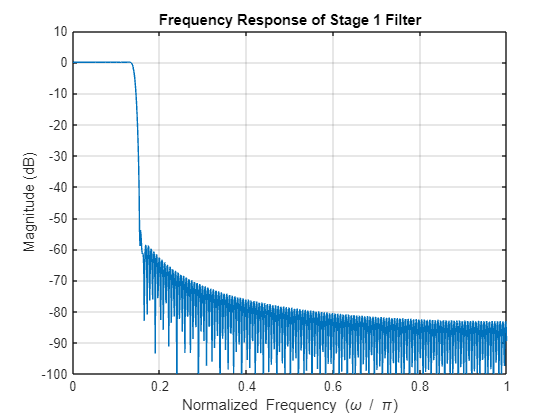

Error using reshape
Product of known dimensions, 7, not divisible into total number of elements, 320.

Error in srconvert>process_stage (line 57)
    H_poly_decim = reshape(h, M, []);  % Decompose the filter into M polyphase components

Error in srconvert (

y = srconvert([1 zeros(1, 3000)]);

verify(y);
